addpath ../bench/benchmarks
addpath ../bench
addpath ../grouping/lib


clear all;close all;clc;


% do not modify these parameters
PERM_GT = false;
isBoosting = false;
boosting_iter = 1;

%%%%%%%%%%%%%%%%%%%methods spec%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%% sample files%%%%%%%%%%%%%%%%%%%%%%
% files that lists "weight, contentId, styleId" at each row
% for universal style transfer, model weights from 0 to 1 is linearly mapped
% to 0 to 2000 to accommendate evaluations on Gatys and Crosslayer. 
sample_file = './wcs3.txt'; 
this_trial = 'round1';

% %first batch 300 samples from gatys
% method = 'Gatys';
% imgFolder = 'Gatysampled15';

% %first batch 300 samples from crosslayer
% method = 'CrossLayer';
% imgFolder = 'AddCrossampled15';

%first batch 300 samples from universal style transfer
method = 'Universal';
imgFolder = 'AddCrossampled15';


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
img_dir = '../BSDS500/data/images';
gtDir = '../BSDS500/data/groundTruth';
rstDir = '../BSDS500/ucm2/SampleTests';

SampleImgDir = fullfile(img_dir,imgFolder);
rstDir = fullfile(rstDir,method);

PbOutDir = fullfile(rstDir,'PbRsts');

if PERM_GT == 0
    gtDir = fullfile(gtDir,'test');
else
    gtDir = fullfile(gtDir,'test_selected_perm');
end
   
if PERM_GT ==0
    EvalOutDir = fullfile(rstDir,strcat(this_trial,'_eval'));
    Eval_stat_outDir = fullfile(rstDir,strcat(this_trial,'_eval_sum'));
else
    EvalOutDir = fullfile(rstDir,strcat(this_trial,'_perm_eval'));
    Eval_stat_outDir = fullfile(rstDir,strcat(this_trial,'_perm_eval_sum'));
end

mkdir(EvalOutDir);

mkdir(Eval_stat_outDir);

samples = dlmread(sample_file);
disp(samples);

           1      123057           1         100
           1      123057           1        1000
           1      123057           2         100
           1      123057           2        1000
           1      123057           3         100
           1      123057           3        1000
           1      123057           4         100
           1      123057           4        1000
           1      123057           5         100
           1      123057           5        1000



image_names = getImgnamesBySample(samples); % return an cell array of image filenames, copy images to directory
mkdir(PbOutDir);

style1_content123057_gramMatrix_iteration100.png  


style1_content123057_gramMatrix_iteration1000.png  


style1_content123057_Pearson_iteration100.png  



converting RGB to grayscale             [0.012055 sec]
converting RGB to Lab                   [0.063262 sec]
quantizing color channels               [0.003202 sec]
computing filter set for textons        [0.006889 sec]
computing textons                       [8.31033 sec]
computing bg                            r = 3 [2.8091 sec]
computing bg                            r = 5 [3.20402 sec]
computing bg                            r = 10 [3.78103 sec]
computing cg_a                          r = 5 [2.17489 sec]
computing cg_a                          r = 10 [2.82936 sec]
computing cg_a                          r = 20 [4.56175 sec]
computing cg_b                          r = 5 [2.45084 sec]
computing cg_b                          r = 10 [2.69734 sec]
computing cg_b                          r = 20 [4.41568 sec]
computing tg                            r = 5 [1.33543 sec]
computing tg                            r = 10 [1.83027 sec]
computing tg                            r = 20 [3.79877 sec]


=== Generalized eigenvalue problem A*x = lambda*B*x ===

The eigenvalue problem is real symmetric.
Matrix B is symmetric positive (semi-)definite.

Computing 17 eigenvalues of type 'smallestabs'.


Parameters passed to Krylov-Schur method:
  Maximum number of iterations: 300
  Tolerance: 1e-14
  Subspace Dimension: 34

Find eigenvalues of R*A\(R'*y) = mu*y, with y = R*x, B = R'*R.
No need to compute R, as it is only used implicitly.
Compute decomposition of A...

--- Start of Krylov-Schur method ---
Iteration   1: 11 of 17 eigenvalues converged. Smallest non-converged residual 9.5e-09 (tolerance 1.0e-14).
Iteration   2: 12 of 17 eigenvalues converged. Smallest non-converged residual 2.4e-10 (tolerance 1.0e-14).
Iteration   3: 13 of 17 eigenvalues converged. Smallest non-converged residual 8.5e-12 (tolerance 1.0e-14).
Iteration   4: 17 of 17 eigenvalues converged.


compute contours                        [0.916896 sec]
returning results                       [0.03337 sec]


  Columns 1 through 20

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

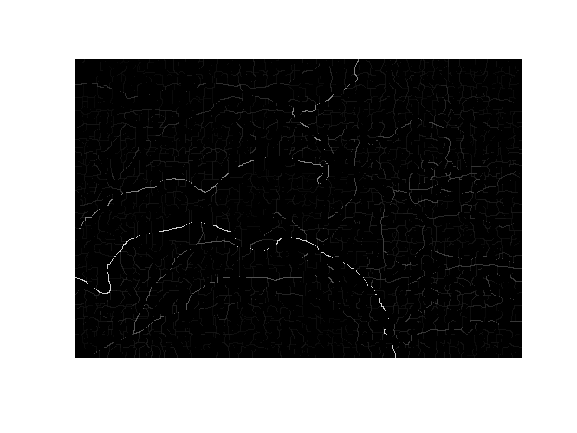

style1_content123057_Pearson_iteration1000.png  


style1_content123057_Covariance_iteration100.png  



converting RGB to grayscale             [0.007532 sec]
converting RGB to Lab                   [0.067439 sec]
quantizing color channels               [0.002371 sec]
computing filter set for textons        [0.00583 sec]
computing textons                       [8.05642 sec]
computing bg                            r = 3 [2.81238 sec]
computing bg                            r = 5 [2.78003 sec]
computing bg                            r = 10 [3.32145 sec]
computing cg_a                          r = 5 [2.11426 sec]
computing cg_a                          r = 10 [2.84566 sec]
computing cg_a                          r = 20 [4.43535 sec]
computing cg_b                          r = 5 [2.10779 sec]
computing cg_b                          r = 10 [2.69651 sec]
computing cg_b                          r = 20 [4.40841 sec]
computing tg                            r = 5 [1.85283 sec]
computing tg                            r = 10 [2.0009 sec]
computing tg                            r = 20 [3.62207 sec]
 

=== Generalized eigenvalue problem A*x = lambda*B*x ===

The eigenvalue problem is real symmetric.
Matrix B is symmetric positive (semi-)definite.

Computing 17 eigenvalues of type 'smallestabs'.


Parameters passed to Krylov-Schur method:
  Maximum number of iterations: 300
  Tolerance: 1e-14
  Subspace Dimension: 34

Find eigenvalues of R*A\(R'*y) = mu*y, with y = R*x, B = R'*R.
No need to compute R, as it is only used implicitly.
Compute decomposition of A...

--- Start of Krylov-Schur method ---
Iteration   1: 12 of 17 eigenvalues converged. Smallest non-converged residual 2.0e-09 (tolerance 1.0e-14).
Iteration   2: 13 of 17 eigenvalues converged. Smallest non-converged residual 6.6e-12 (tolerance 1.0e-14).
Iteration   3: 15 of 17 eigenvalues converged. Smallest non-converged residual 5.8e-12 (tolerance 1.0e-14).
Iteration   4: 16 of 17 eigenvalues converged. Smallest non-converged residual 2.7e-13 (tolerance 1.0e-14).
Iteration   5: 17 of 17 eigenvalues converged.


compute contours                        [0.563242 sec]
returning results                       [0.033988 sec]


  Columns 1 through 20

         0         0         0         0         0         0         0         0         0         0         0         0    0.0488         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    0.0488         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    0.0488         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    0.0488         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    0.0488         0         0         0         0  

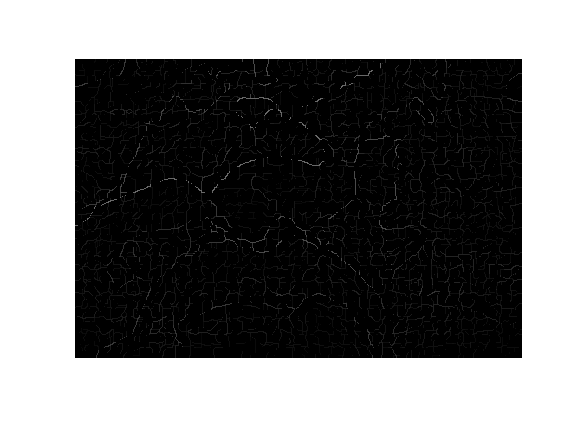

style1_content123057_Covariance_iteration1000.png  


style1_content123057_Euclidean_iteration100.png  



converting RGB to grayscale             [0.011889 sec]
converting RGB to Lab                   [0.051148 sec]
quantizing color channels               [0.002314 sec]
computing filter set for textons        [0.005685 sec]
computing textons                       [8.05141 sec]
computing bg                            r = 3 [2.68835 sec]
computing bg                            r = 5 [2.75431 sec]
computing bg                            r = 10 [3.31602 sec]
computing cg_a                          r = 5 [2.23095 sec]
computing cg_a                          r = 10 [2.732 sec]
computing cg_a                          r = 20 [4.99771 sec]
computing cg_b                          r = 5 [2.09918 sec]
computing cg_b                          r = 10 [2.68912 sec]
computing cg_b                          r = 20 [4.38299 sec]
computing tg                            r = 5 [1.30505 sec]
computing tg                            r = 10 [1.80689 sec]
computing tg                            r = 20 [3.74869 sec]
 

=== Generalized eigenvalue problem A*x = lambda*B*x ===

The eigenvalue problem is real symmetric.
Matrix B is symmetric positive (semi-)definite.

Computing 17 eigenvalues of type 'smallestabs'.


Parameters passed to Krylov-Schur method:
  Maximum number of iterations: 300
  Tolerance: 1e-14
  Subspace Dimension: 34

Find eigenvalues of R*A\(R'*y) = mu*y, with y = R*x, B = R'*R.
No need to compute R, as it is only used implicitly.
Compute decomposition of A...

--- Start of Krylov-Schur method ---
Iteration   1: 12 of 17 eigenvalues converged. Smallest non-converged residual 1.6e-08 (tolerance 1.0e-14).
Iteration   2: 13 of 17 eigenvalues converged. Smallest non-converged residual 3.1e-11 (tolerance 1.0e-14).
Iteration   3: 14 of 17 eigenvalues converged. Smallest non-converged residual 5.7e-12 (tolerance 1.0e-14).
Iteration   4: 17 of 17 eigenvalues converged.


compute contours                        [0.562749 sec]
returning results                       [0.031066 sec]


  Columns 1 through 20

         0         0         0         0         0         0         0         0         0         0    0.0405         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0    0.0405         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    0.0405    0.0405    0.0405         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    0.0405         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    0.0405         0         0         0         0         0         0         0         0  

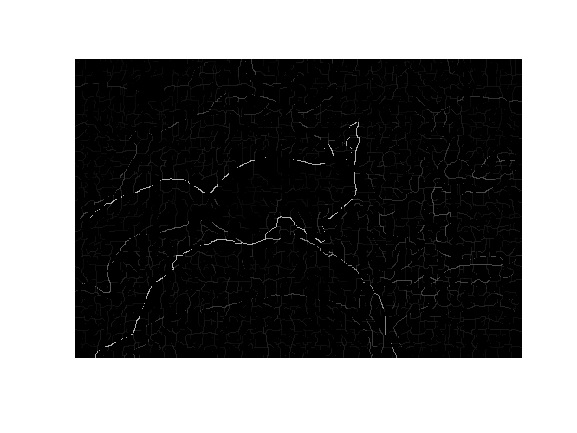

style1_content123057_Euclidean_iteration1000.png  


style1_content123057_CosineSimilarity_iteration100.png  



converting RGB to grayscale             [0.011798 sec]
converting RGB to Lab                   [0.049446 sec]
quantizing color channels               [0.002375 sec]
computing filter set for textons        [0.005544 sec]
computing textons                       [8.04585 sec]
computing bg                            r = 3 [2.68219 sec]
computing bg                            r = 5 [2.79718 sec]
computing bg                            r = 10 [3.39021 sec]
computing cg_a                          r = 5 [2.04474 sec]
computing cg_a                          r = 10 [2.50339 sec]
computing cg_a                          r = 20 [4.38028 sec]
computing cg_b                          r = 5 [2.05796 sec]
computing cg_b                          r = 10 [2.76492 sec]
computing cg_b                          r = 20 [4.47004 sec]
computing tg                            r = 5 [1.3831 sec]
computing tg                            r = 10 [1.85525 sec]
computing tg                            r = 20 [3.71412 sec]


=== Generalized eigenvalue problem A*x = lambda*B*x ===

The eigenvalue problem is real symmetric.
Matrix B is symmetric positive (semi-)definite.

Computing 17 eigenvalues of type 'smallestabs'.


Parameters passed to Krylov-Schur method:
  Maximum number of iterations: 300
  Tolerance: 1e-14
  Subspace Dimension: 34

Find eigenvalues of R*A\(R'*y) = mu*y, with y = R*x, B = R'*R.
No need to compute R, as it is only used implicitly.
Compute decomposition of A...

--- Start of Krylov-Schur method ---
Iteration   1: 12 of 17 eigenvalues converged. Smallest non-converged residual 1.9e-10 (tolerance 1.0e-14).
Iteration   2: 13 of 17 eigenvalues converged. Smallest non-converged residual 2.9e-07 (tolerance 1.0e-14).
Iteration   3: 13 of 17 eigenvalues converged. Smallest non-converged residual 3.4e-12 (tolerance 1.0e-14).
Iteration   4: 17 of 17 eigenvalues converged.


compute contours                        [4.75884 sec]
returning results                       [0.112217 sec]


  Columns 1 through 20

         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0    1.0000         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0    1.0000         0         0         0    1.0000         0
         0         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000         0
         0         0         0         0    1.0000         0         0         0    1.0000         0         0         0         0         0    1.0000         0         0         0         0         0
    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0  

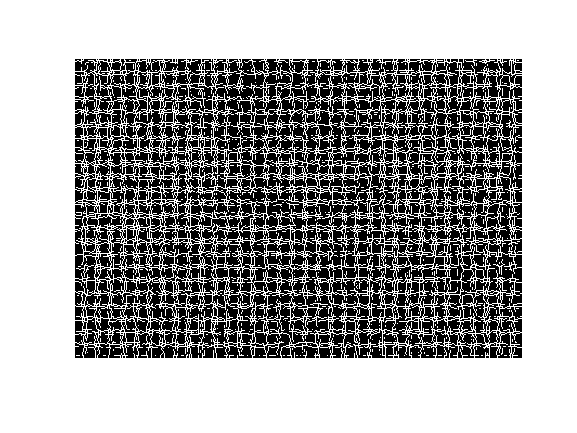

style1_content123057_CosineSimilarity_iteration1000.png  




all_file_dir(1:length(image_names)) = struct('name',[],'folder',[],'date',[],'bytes',[],'isdir',[],'datenum',[]);

% change for to parfor if parallel package is available
for i =1:numel(image_names)
    
    PbOutFile = fullfile(PbOutDir,[image_names{i}(1:end-4) '.mat']); 
    imgFile=fullfile(SampleImgDir,image_names{i});
    
    if ~exist(imgFile,'file')
        imgFile = strrep(imgFile,'.png','.jpg');
    end
    
    dir(imgFile)
    all_file_dir(i) = dir(imgFile);
    if exist(PbOutFile,'file'), continue; end
    %[ucm2] = im2ucm(imgFile, PbOutFile);
    gPb_orient = globalPb(imgFile, PbOutFile);
    ucm2 = contours2ucm(gPb_orient, 'doubleSize');

    save(PbOutFile,'ucm2');
    disp(ucm2);
    figure; imshow(ucm2);
end

for i =1:numel(image_names)
    imgFile=fullfile(SampleImgDir,image_names{i});
    filename_splits = strsplit(dir(imgFile).name,'_');
    gt_file_name = strrep(filename_splits{2},'content','');    
    gtFile = fullfile(gtDir, strcat(gt_file_name,'.mat'));
    
    evFile = fullfile(EvalOutDir, strcat(dir(imgFile).name(1:end-4),'_ev1.txt'));
    S = dir(fullfile(EvalOutDir, strcat(dir(imgFile).name(1:end-4),'_*')));
    num = length(S)+1;
    evFile_new = fullfile(EvalOutDir, strcat(dir(imgFile).name(1:end-4),'_',num2str(num),'_ev1.txt'));
    %copyfile(evFile,evFile_new)
    evaluation_bdry_image(PbOutFile, gtFile, evFile)
end

ans =     0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900
    0.1000


ans =     0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900
    0.1000


ans =     0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900
    0.1000


ans =     0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900
    0.1000


ans =     0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900
    0.1000


iter =1;
if isBoosting, iter = boosting_iter;end 
sum_AUC = zeros(iter,1); 
   
for k=1:iter
   fprintf('iter: %d\n',k)
    % randomly sample image to evaluate, sort of like boosting
    if isBoosting,
        iids = cell(length(image_names),1);

        for j = 1:numel(all_file_dir),      
            iids{j} = all_file_dir(randi(length(all_file_dir))).name;
        end
    else
        iids = all_file_dir;
    end
    
    %  get per image AUCs
    eval_file_dirs = fullfile(EvalOutDir,strrep(strrep({iids.name},'.png','_ev1.txt'),'.jpg','_ev1.txt'));
    AUCs = zeros(length(eval_file_dirs),1);
    
    this_weight_eval_stat_ourDir = fullfile(Eval_stat_outDir,'all');
    mkdir(this_weight_eval_stat_ourDir);
        
    for j = 1:length(eval_file_dirs)

       [bestF, bestP, bestR, bestT, F_max, P_max, R_max, Area_PR] = collect_eval_bdry_sty(this_weight_eval_stat_ourDir,eval_file_dirs(j));
        AUCs(j) = Area_PR;
        
    end
      rsts =[num2str(samples) [' ';' ';' ';' ';' '] num2str(AUCs)];
     save(fullfile(this_weight_eval_stat_ourDir,[method '_everyImgAUC.mat']),'rsts');
    
end 

iter: 1


Processing image ../BSDS500/ucm2/SampleTests/Universal/round1_eval/style1_content123057_gramMatrix_iteration1000 (1/1)...
Processing image ../BSDS500/ucm2/SampleTests/Universal/round1_eval/style1_content123057_Pearson_iteration1000 (1/1)...
Processing image ../BSDS500/ucm2/SampleTests/Universal/round1_eval/style1_content123057_Covariance_iteration1000 (1/1)...
Processing image ../BSDS500/ucm2/SampleTests/Universal/round1_eval/style1_content123057_Euclidean_iteration1000 (1/1)...
Processing image ../BSDS500/ucm2/SampleTests/Universal/round1_eval/style1_content123057_CosineSimilarity_iteration1000 (1/1)...
